3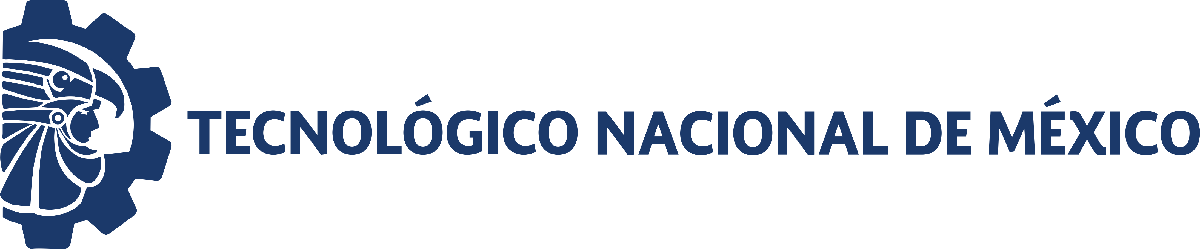                                 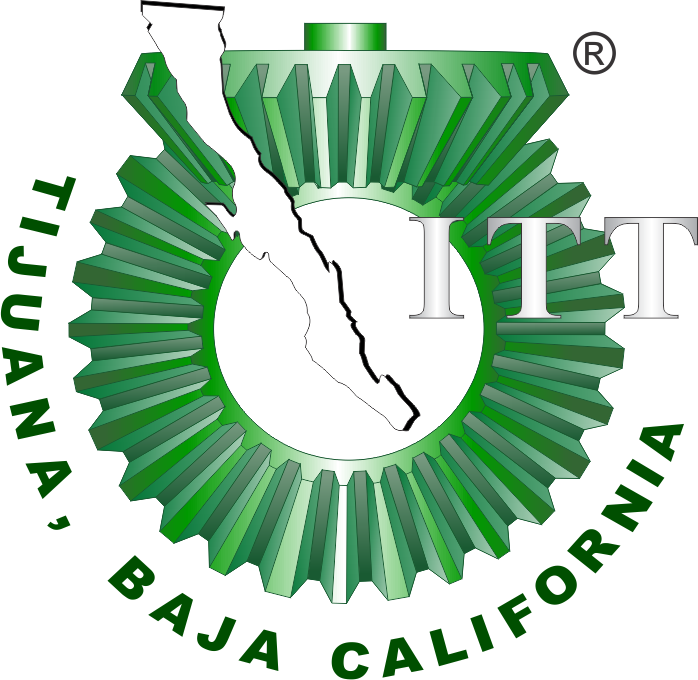

# Práctica cuatro: Modelado y control del sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

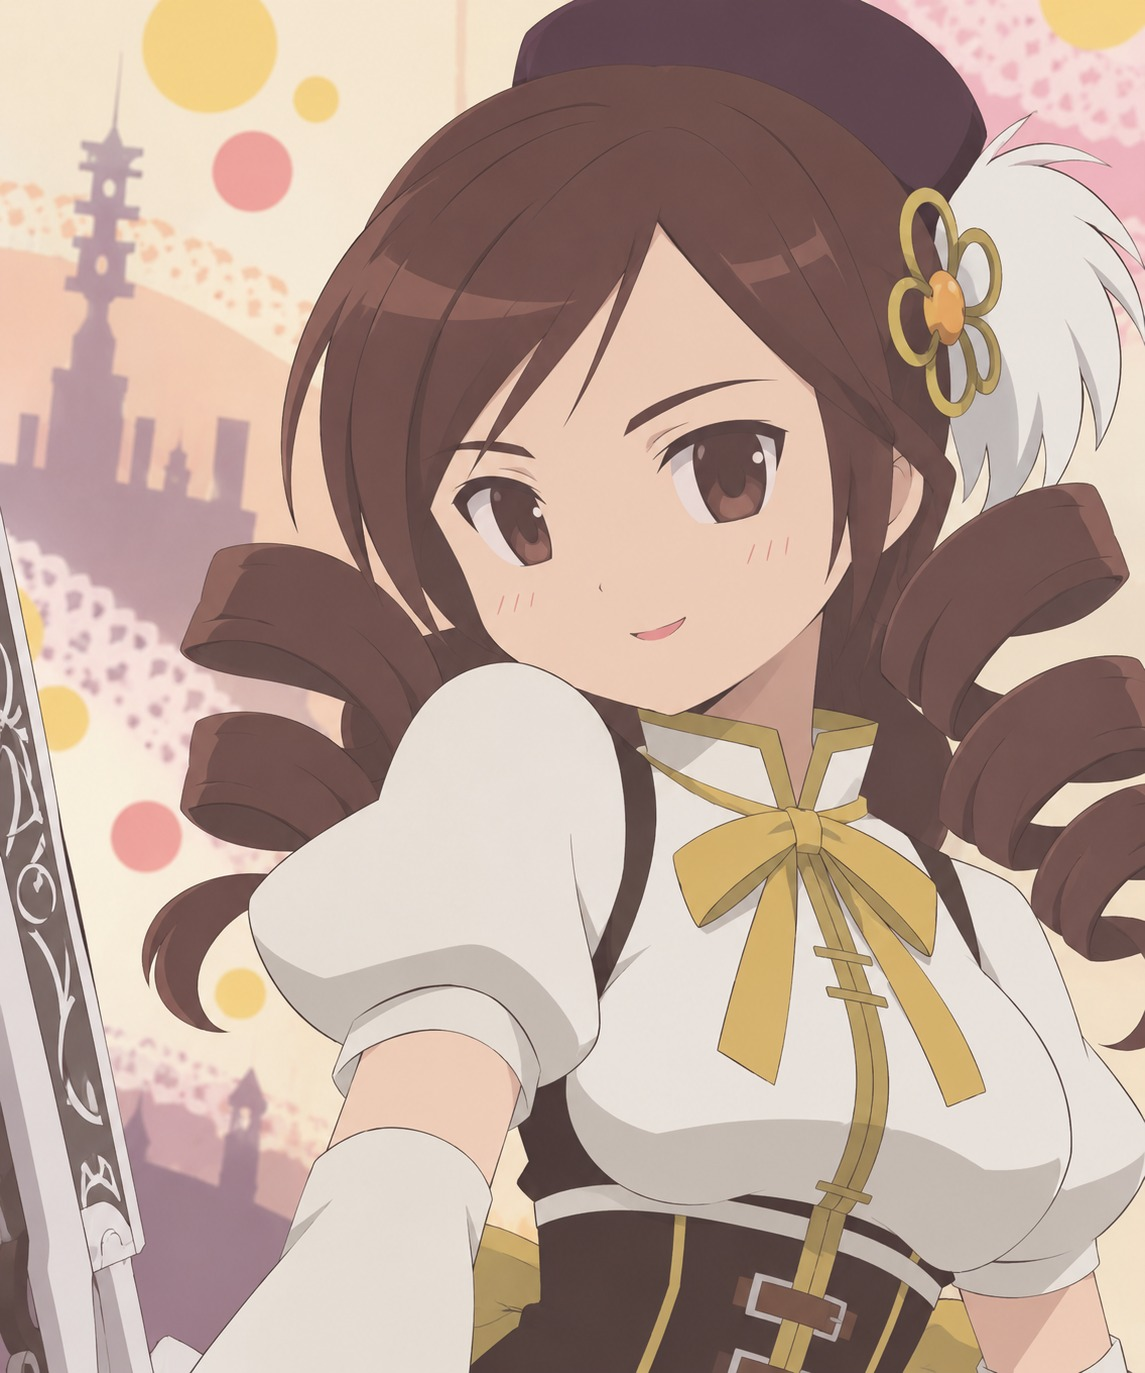

Nombre del alumno:** Judith Valeria Soriano Angeles**

Número de control:** 23212231**

Correo institucional:** 23212231@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta: Control y Caso

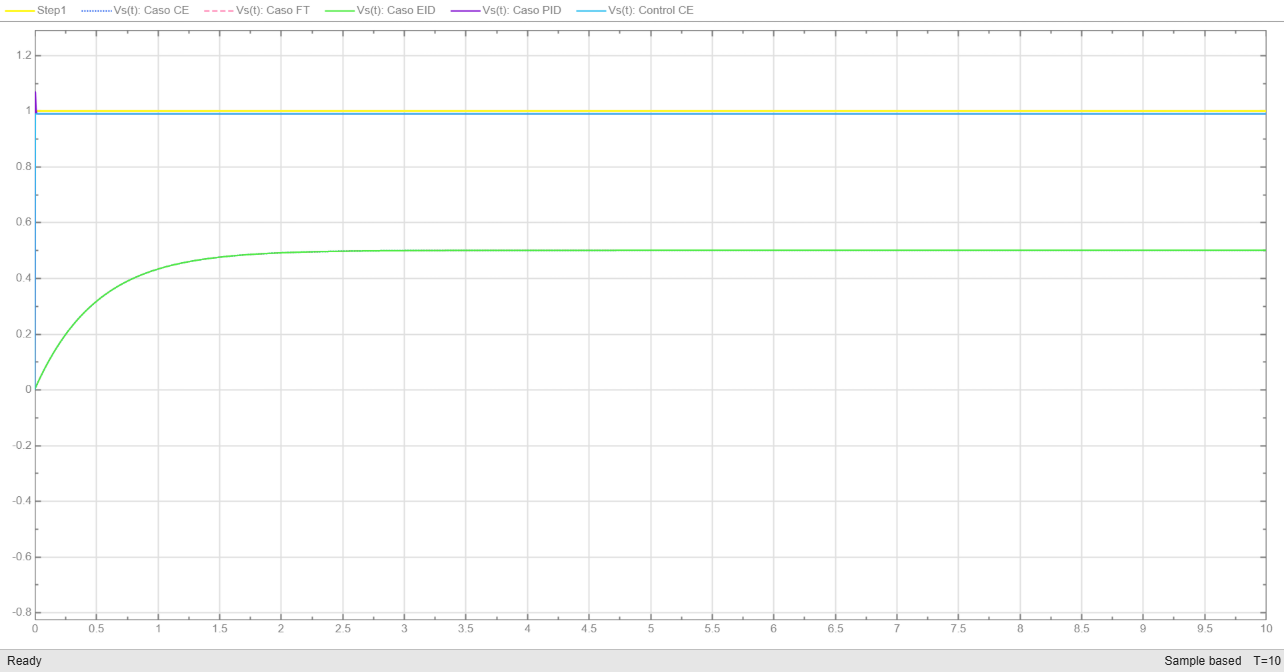

x = sim('Sistema',parameters);

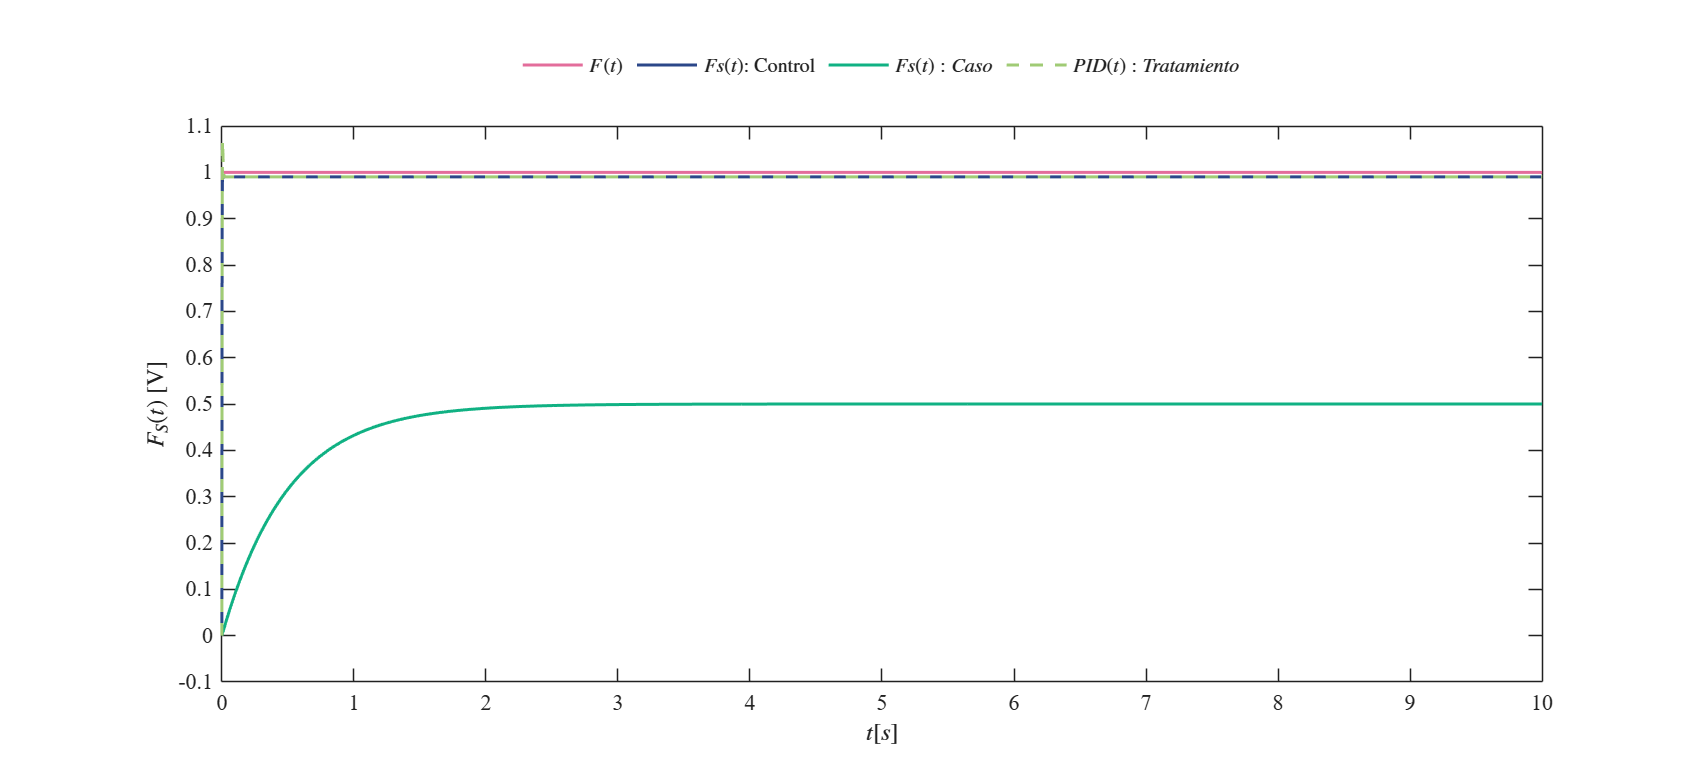

plotsignals(x.t,x.Ve,x.Fsx,x.Fsy,x.PID,'Caso');

## Función: Respuesta de la simulación

function plotsignals(t,Ve,Fsx,Fsy,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,18,8])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [227, 109, 155] / 255; %rosa
    clr2 = [43, 71, 137] / 255; %azul
    clr3 = [16, 177, 131] / 255; %verde oscuro 
    clr4 =  [160, 203, 117] / 255; %verde claro
    order = [clr1; clr2; clr3; clr4]; colororder(order)

    plot(t,Ve,'-',t,Fsx,'-',t,Fsy,'-',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));

    L = legend('$F(t)$','$Fs(t)$: Control','$Fs(t): Caso$','$PID(t): Tratamiento$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal', 'Box', 'off', 'NumColumns', 4)

    xlabel('$ t[s]$','Interpreter','latex')
    ylabel('$F_S(t)$ [V]', 'Interpreter','latex')

    xlim([0 10]); xticks(0:1:10)

    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    exportgraphics(gcf, [signal,'_matlab.pdf'], 'ContentType', 'vector')

end